%% Exercise 1, Solution
%
% 代码说明：
%   解决 x+ = Ax 这种 invariant set，没有输入控制 u

clc; close all; clear;

% 系统设置
alpha = pi/6; 
beta  = 0.8;
A = [cos(alpha) sin(alpha); 
    -sin(alpha) cos(alpha)]*beta;
Ax = [cos(pi/3) sin(pi/3); -cos(pi/3) -sin(pi/3);...
	sin(pi/3) -cos(pi/3); -sin(pi/3) cos(pi/3)];
bx = [2;1;2;5];

X = polytope(Ax,bx);

% 绘制约束
figure(1); clf; axis equal; hold on;
h1=plot(X, 'b');


% 计算 maximal invariant set
i = 1;
O = X;
while i <= 50
	Oprev = O;
	[F,f] = double(O);	
	% Compute the pre-set
	O = polytope([F;F*A],[f;f]);
    test = polytope(F*A,f); % 添加测试
    plot(test,'c')
	if O == Oprev, break; end
	
	h2=plot(O, 'y');
	fprintf('Iteration %i... not yet equal\n', i)
	% pause

	i = i + 1;
end

Iteration 1... not yet equal
Iteration 2... not yet equal
Iteration 3... not yet equal
Iteration 4... not yet equal


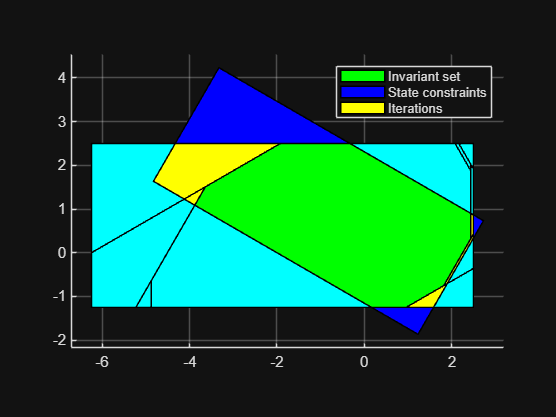

% fprintf('Maximal invariant set computed after %i iterations\n\n', i);
h3=plot(O,'g');
legend([h3;h1;h2],{'Invariant set';'State constraints';'Iterations'});

%% Exercise 2, Solution
%
% 代码说明：
%   解决 x+ = Ax + Bu Control Invariant Set


clc; close all; clear;

% 系统参数
alpha = pi/6; 
beta  = 0.8;
A = [cos(alpha) sin(alpha); 
    -sin(alpha) cos(alpha)]*beta;
B = [0.5;
     0.5];

Ax = [cos(pi/3)  sin(pi/3); 
     -cos(pi/3) -sin(pi/3);
	  sin(pi/3) -cos(pi/3); 
     -sin(pi/3)  cos(pi/3)];
bx = [2;1;2;5];

Hu = [1;-1]; hu = [0.5;0.5];


X = polytope(Ax,bx);
U = polytope(Hu,hu);


% 绘制约束
figure(1); clf; axis equal;
h1 = plot(X, 'b');
hold on;

% 计算 maximal invariant set
i = 1;
O = polytope(Ax,bx);
while 1
	Oprev = O;
	[F,f] = double(O);	
	% Compute the pre-set
	O = intersect(O, projection(polytope([F*A F*B; zeros(2) Hu],[f;hu]), 1:2));
	if O == Oprev, break; end
	
	h2=plot(O, 'y');
	fprintf('Iteration %i... not yet equal\n', i)
	% pause

	i = i + 1;
end

Iteration 1... not yet equal
Iteration 2... not yet equal


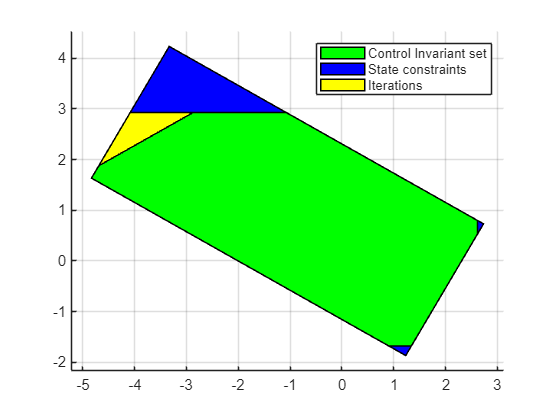

% fprintf('Maximal control invariant set computed after %i iterations\n\n', i);
h3=plot(O,'g');
legend([h3;h1;h2],{'Control Invariant set';'State constraints';'Iterations'});

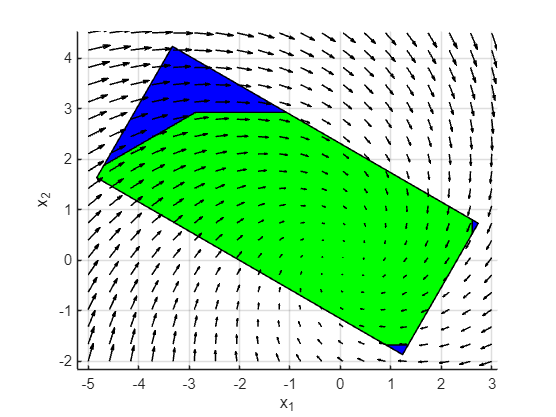

% 绘制矢量场
addpath('Function')
figure; hold on; axis equal; grid on;
X.plot('color','b','alpha',1.0);
O.plot('color','g','alpha',1.0);
Plot_Vector_Field(A,[-5,3],[-2,4.5]);
hold off;